# Exercise 6 regbot

## Plot data from the log txt file

data_wu = readtable('C:\Users\Alonso\Desktop\REGBOT\Ex_6\regbot_log_6_wu.txt');
data_wu = fillmissing(data_wu, 'nearest');
data_wd = readtable('C:\Users\Alonso\Desktop\REGBOT\Ex_6\log_6_wd.txt');
data_wd = fillmissing(data_wd, 'nearest');
data_wu_filter = readtable('C:\Users\Alonso\Desktop\REGBOT\Ex_6\log_6_wu_filtered.txt');
data_wu_filter = fillmissing(data_wu_filter, 'nearest');

[t_wu,u_L_wu,u_R_wu,v_L_wu,v_R_wu,T_s_wu] = get_data(data_wu,8,9,10,11);
[t_wd,u_L_wd,u_R_wd,v_L_wd,v_R_wd,T_s_wd] = get_data(data_wd,2,3,4,5);
[t_wu_fil,u_L_fil,u_R_fil,v_L_fil,v_R_fil,T_s_fil] = get_data(data_wu_filter,2,3,4,5);

## Wheels up

idwu = find(u_L_wu >= 4,1,'first');
idwu = idwu - 20;
idd_L_wu = iddata(v_L_wu(idwu:end),u_L_wu(idwu:end),T_s_wu);
G_L_wu = tfest(idd_L_wu,2,0)  

G_L_wu =
 
  From input "u1" to output "y1":
         327.9
  --------------------
  s^2 + 96.08 s + 1093
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                              
Estimated using TFEST on time domain data "idd_L_wu".
Fit to estimation data: 81.48%                       
FPE: 0.0001974, MSE: 0.0001947                       




%[y_A,t_A] = step(G_L_wu,t(end));
%figure
%plot(t_A,y_A);
%hold on
%hold off
%legend('Estimated out','Measured out');

## Wheels down

idwd = find(u_L_wd >= 4,1,'first');
idwd = idwd + 42;
idd_L_wd = iddata(v_L_wd(idwd:end),u_L_wd(idwd:end),T_s_wd);
G_L_wd = tfest(idd_L_wd,2,0) 

G_L_wd =
 
  From input "u1" to output "y1":
          12.1
  ---------------------
  s^2 + 12.67 s + 42.81
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 2   Number of zeros: 0
   Number of free coefficients: 3
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                              
Estimated using TFEST on time domain data "idd_L_wd".
Fit to estimation data: 41.45%                       
FPE: 0.001048, MSE: 0.001043                         


%[y_A,t_A] = step(G_L_wd,t(end));
% figure
% plot(t_A,y_A);
% hold on
% hold off
% legend('Estimated out','Measured out');

## Bode diagrams

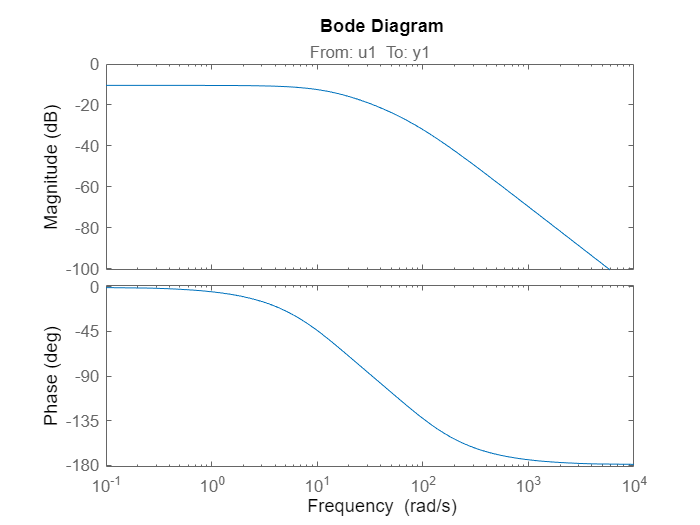

bode(G_L_wu)

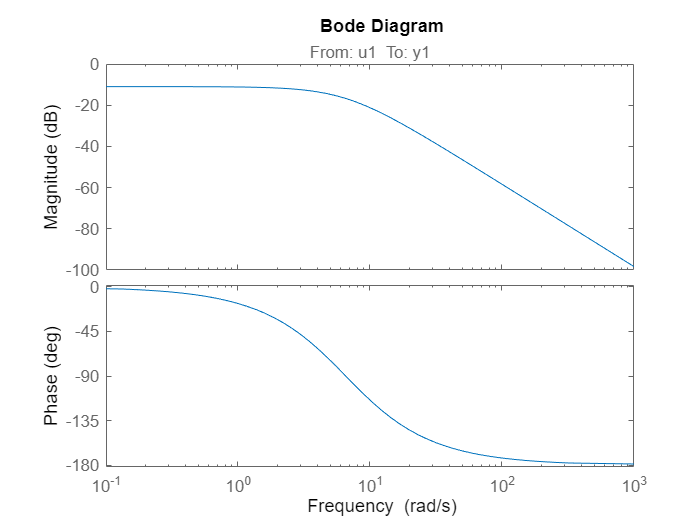

bode(G_L_wd)

%idd_L_wu_after = iddata(v_L_wu_after,u_L_wu_after,T_s_wu_after);
%G_L_after = tfest(idd_L_wu_after,2,0) 

## Step 2: find break frequency and phase margin

%From previous exercise
Kp = 10^(10.4569/20); %% We dont really know the value, I supposed it was 1

G_ol = Kp*G_L_wu

G_ol =
 
  From input "u1" to output:
          1093
  --------------------
  s^2 + 96.08 s + 1093
 
Continuous-time transfer function.



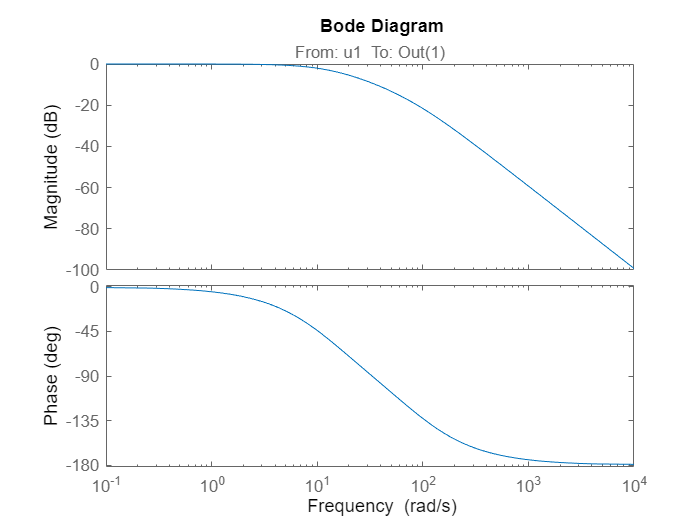

bode(G_ol)

%a,b = margin(G_ol,{deg2rad(0),deg2rad(-179)}) %The system doesnt reach -180 so it tends to infinite [TA] ------>(should we approximate the margin to -179???)
%break_freq is located at -3dB
break_freq = 13

break_freq = 13

## Step 3: Apply filter

filter = tf(break_freq,[1 break_freq])

filter =
 
    13
  ------
  s + 13
 
Continuous-time transfer function.



G_ol_fil = G_ol *  filter

G_ol_fil =
 
               1.421e04
  -----------------------------------
  s^3 + 109.1 s^2 + 2342 s + 1.421e04
 
Continuous-time transfer function.



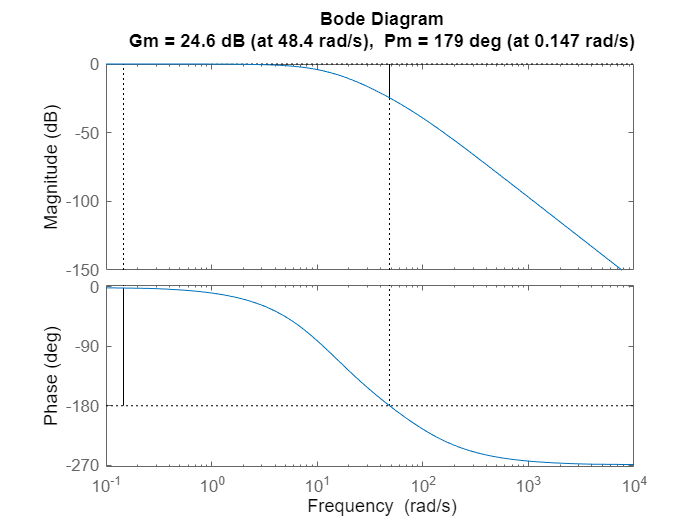

margin(G_ol_fil)

[Gm,Pm,W_pi,W_cross] = margin(G_ol_fil)

Gm = 16.9805

Pm = 178.6161

W_pi = 48.3957

W_cross = 0.1465

## Step 3 part 2 ?????

% new_break_frequency = 0.5
% filter = tf(new_break_frequency,[1 new_break_frequency])
% G_ol_fil = G_ol *  filter
% step(G_ol_fil)
% bode(G_ol_fil)
% margin(G_ol_fil)
% [Gm,Pm,W_pi,W_cross] = margin(G_ol_fil)

## Step 4: BodePlot && Step Response

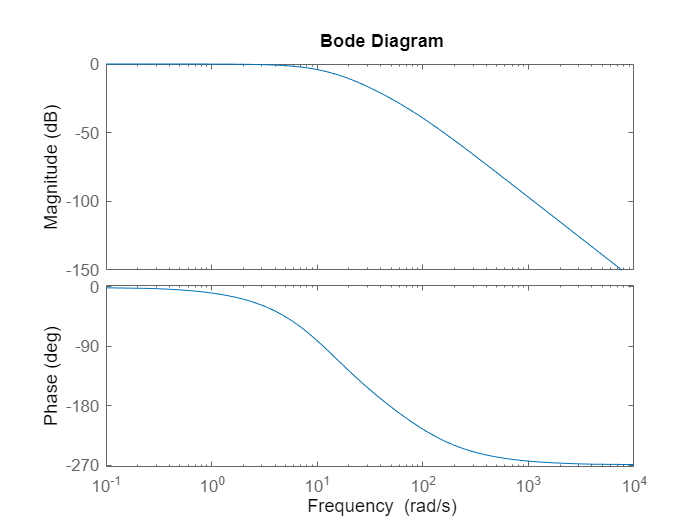

bode(G_ol_fil)

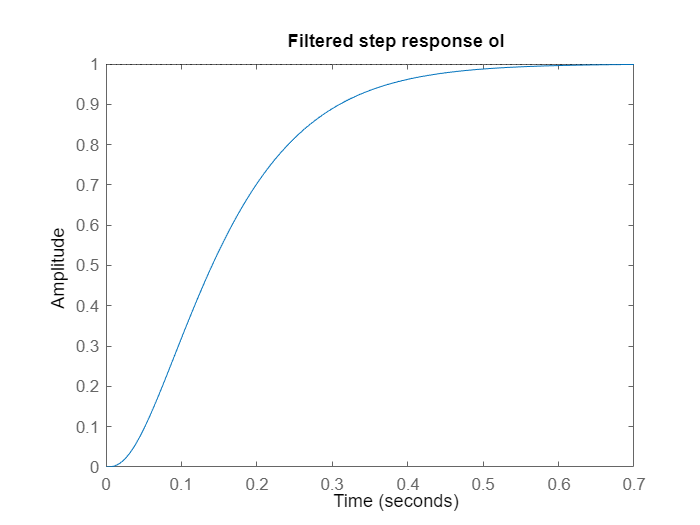


step(G_ol_fil)
title('Filtered step response ol')

## Step 5 : Close loop tf

%Kp = 0.2
G_cl = Kp * G_ol / (1 + Kp * G_ol * filter)

G_cl =
 
             3643 s^3 + 3.974e05 s^2 + 8.531e06 s + 5.176e07
  ---------------------------------------------------------------------
  s^5 + 205.2 s^4 + 1.391e04 s^3 + 4.058e05 s^2 + 8.474e06 s + 6.728e07
 
Continuous-time transfer function.



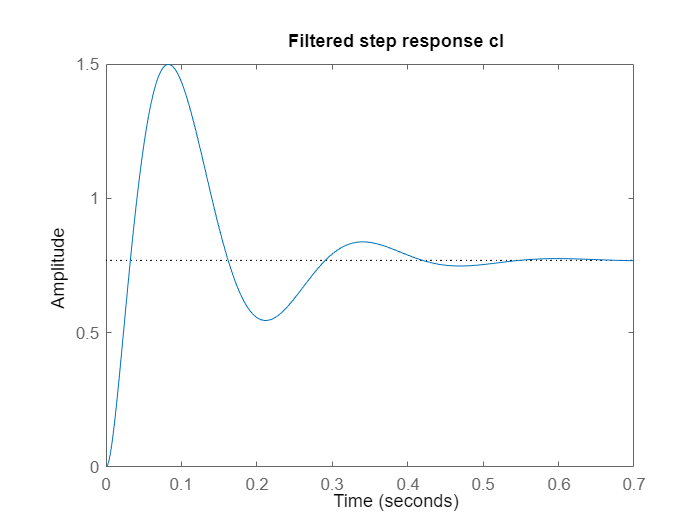

step(G_cl)
title('Filtered step response cl')

## Step 7:

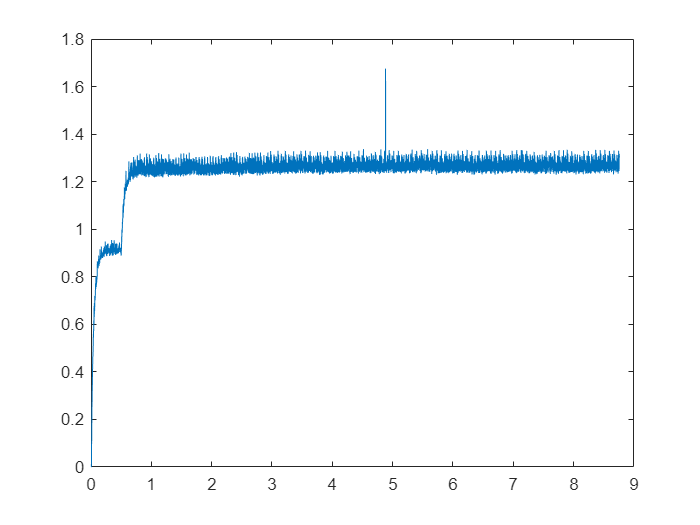

plot(t_wu_fil,v_L_fil) %SI but velocities do not match cause left wheel gets stucked somehow

function [t,u_L,u_R,v_L,v_R,T_s] = get_data(data,a,b,c,d)
    t = table2array(data(:,1));     % time stamps
    u_L = table2array(data(:,a));   % left motor voltage
    u_R = table2array(data(:,b));   % right motor voltage
    v_L = table2array(data(:,c));  % left motor velocity 
    v_R = table2array(data(:,d));  % right motor velocity
    T_s = t(2) - t(1);              % compute sampling time
end